**Name : Krish Singh**

**Roll: AID25072**

**Branch: B.Tech AI & DS 2nd sem**

*1.  Pseudoinverse of an m×n matrix, A  Every matrix Am×n has a pseudoinverse A+ or pinv(A)  • If m = n = rank of A, then A is invertible and A+ = A-1  • If rank of A = n, (all columns of A are independent), then A+ = (ATA)-1AT = Left  Inverse of A, and A+A = In.  • If rank of A = m, (all rows of A are independent), then A+ = AT (AAT)-1 = Right Inverse  of A, and AA+ = Im.  • Pseudoinverse A+ of any matrix A can be obtained in MATLAB using the command  ‘pinv(A)’.*

 a. Generate a 9×9 random integer matrix and verify that inv(A) = pinv(A). 

A=randi([0,9],9,9);
ainv=inv(A);
painv=pinv(A);
if norm(ainv-painv)<1e-10
    disp("Inverse of A is equal to pseudoinverse of A");
else
    disp("Inverse of A is not equal to pseudoinverse of A");
end

Inverse of A is equal to pseudoinverse of A


b. Generate a 5×4 random integer matrix and verify that pinv(A) is same as the left  inverse of A.

A=randi([0,9],5,4);
apinv=pinv(A);
lainv=inv(A'*A)*A';
if norm(apinv-lainv)<1e-10
    disp("Pseudoinverse of A is equal to left inverse of A");
else
    disp("Pseudoinverse of A is not equal to left inverse of A");
end

Pseudoinverse of A is equal to left inverse of A


c. Generate a 3×7 random integer matrix and verify that pinv(A) is same as the right  inverse of A. 

A=randi([0,9],3,7);
apinv=pinv(A);
arinv=A'*inv(A*A');
if norm(apinv-arinv)<1e-10
    disp("Pseudonverse of A is equal to Right inverse");
else
    disp("Pseudoinverse of A is not equal to Right inverse");
end

Pseudonverse of A is equal to Right inverse


*2. Projection of a vector v on a subspace S, which is a column space of matrix A(with all  independent columns)  is p = A(ATA)-1ATv.   If some columns in A are dependent (i.e., if Rank(Am×n) < n), then the projection of a  vector v on a subspace S, which is a column space of matrix A is p = A*pinv(A)*v, where  pinv(A) is the pseudo inverse of A. *

a. Find the projection of 𝑣=( −3 −3 8 9 ) on the space spanned by ( 3 1 0 1 ),( 1 2 1 1 ),( −1 0 2 −1 ).

v=[-3;-3;8;9];
A=[3 1 -1;
    1 2 0;
    0 1 2;
    1 1 -1];
if norm(rank(A)-size(A,2))<1e-10
    p=A*inv(A'*A)*A'*v;
    disp(p);
else
    p=A*pinv(A)*v;
    disp(p);
end

   -2.0000
    3.0000
    4.0000
   -0.0000



b. Find the projection of 𝑢=( 2 1 3 ) on the space spanned by ( 1 1 0 ),( 1 2 1 ). 

u=[2;1;3];
A=[1 1;1 2;0 1];
if norm(rank(A)-size(A,2))
    p=A*inv(A'*A)*A'*u;
    disp(p);
else
    p=A*pinv(A)*u;
    disp(p);
end

    0.6667
    2.3333
    1.6667



c. Find the projection of 𝑢=( 2 1 3 ) on the column space of =( 1 1 2 4; 1 2 3 6; 0 1 1 2 ).

u=[2;1;3];
A=[1 1 2 4; 
1 2 3 6; 
0 1 1 2 ];
if norm(rank(A)-size(A,2))<1e-10
    p=A*inv(A'*A)*A'*u;
    disp(p);
else
    p=A*pinv(A)*u;
    disp(p)
end

    0.6667
    2.3333
    1.6667



*Consider the matrices given below: A, B, C, D and E*

A=[1 4 5 6 9;
    3 -2 1 4 -1;
    -1 0 -1 -2 -1;
    2 3 5 7 8];

B=[3 4; 
    1 8];

C=[0 1 0;
    0 0 1;
    0 4 2];

D=[1 2 0 1;
    0 1 1 0;
    2 4 0 2];

E=[0 1 4 1;
    0 0 8 1;
    0 1 4 0;
    1 0 8 0;
    0 1 1 0;
    1 0 1 0];

a. which one of the matrices have inverse? Find if it exists.

if norm(size(A,1)-size(A,2))<1e-10 && det(A)~=0
    disp("Matrix A has inverse");
else
    disp("Matrix A does not have a inverse");
end

Matrix A does not have a inverse


if norm(size(B,1)-size(B,2))<1e-6 && det(B)~=0
    disp("Matrix B has inverse");
else
    disp("Matrix B does not have inverse");
end

Matrix B has inverse


if norm(size(C,1)-size(C,2))<1e-10 && det(C)~=0
    disp("Matrix C has inverse");
else
    disp("Matrix C does not have inverse");
end

Matrix C does not have inverse


if norm(size(D,1)-size(D,2))<1e-10 && det(D)~=0
    disp("Matrix D has a inverse");
else
    disp("Matrix D does not have a inverse");
end

Matrix D does not have a inverse


if norm(size(E,1)-size(E,2))<1e-10 && det(E)~=0
    disp("Matrix E has a inverse");
else
    disp("Matrix e does not have a inverse");
end

Matrix e does not have a inverse


*3. Least square solution of a linear system, AX=B is:*

*  x̂= (ATA)-1ATb, if all the column vectors in A are independent (i.e. if ATA is invertible).  *

*x̂= pinv(A)*b, if the column vectors in A are not all independent. *

* • Find the least square solution for the following systems: *

a.  x + y = 10; 2x + y = 10; 3x + y = 16; 4x + y = 27; 5x + y = 23. 

A=[1 1;
    2 1;
    3 1;
    4 1;
    5 1];
B=[10;10;16;27;23];
if rank(A)==size(A,2)
    x=(A'*A)\(A'*B);
    disp(x);
else
    x=pinv(A)*B;
    disp(x);
end

    4.3000
    4.3000



b. 2x – 3y + z = 1; x + 3y – 4z = -4; 3x – 2y – z = -1; 5x – y – 4z = -4. 

A=[2 -3 1;
    1 3 -4;
    3 -2 -1;
    5 -1 -4];
B=[1;-4;-1;-4];
if rank(A)==size(A,2)
    x=(A'*A)\(A'*B);
    disp(x);
else
    x=pinv(A)*B;
    disp(x);
end

   -0.3333
   -0.3333
    0.6667



c. 2x + y = 20; 2x - 3y = 4; 3x + y = 28; 4x + y = 36;

A=[2 1;
    2 -3;
    3 1;
    4 1];
B=[20;4;28;36];
if rank(A)==size(A,2)
    x=(A'*A)\(A'*B);
    disp(x);
else
    x=pinv(A)*B;
    disp(x);
end

     8
     4



3. Fit a parabola (quadratic function) with (-2, 0), (-1,0), (0,1), (1, 0), and (2, 0). 

x=[-2 -1 0 1 2];
y=[0 0 1 0 0];
quad=polyfit(x,y,2);
disp("y= "+quad(1)+"x² "+quad(2)+"x "+quad(3));

y= -0.14286x² 1.7053e-17x 0.48571


4. A middle-aged man was stretched on a rack to lengths L = 5, 6, and 7 feet under applied forces of F = 1, 2, and 4 tons. Assuming Hookes law L = a + bF , find his normal length a by leastsquares.  

F=[1;2;4];
L=[5;6;7];
A=[ones(size(F)) F];
x=(A'*A)\(A'*L);
a=x(1);
b=x(2);
disp("Normal length a = "+a);

Normal length a = 4.5


disp("Proportanality constant b = "+b);

Proportanality constant b = 0.64286


5. Find the best straight-line t (least squares) to the measurements: b = 4 at t = -2, b = 3 at t = -1, b = 1 at t = 0 and b = 0 at t = 2. Then find the projection of b = (4; 3; 1; 0) onto the column space of A =[ 1 −2; 1 −1 ;1  0; 1  2 ]

A=[1 -2; 1 -1; 1 0; 1 2];
t=[-2;-1;0;2];
b=[4;3;1;0];
A=[ones(size(t)) t];
x=(A'*A)\(A'*b);
a=x(1);
beta=x(2);
disp("Best-fit line: b=a+beta*t");

Best-fit line: b=a+beta*t


disp("a = "+a+" and "+"beta = "+beta);

a = 1.7429 and beta = -1.0286


bproj=A*x;
disp("projection of b onto col(A):"); disp(bproj);

projection of b onto col(A):
    3.8000
    2.7714
    1.7429
   -0.3143



6. Fit a best straight line passing through (-3, 4),(-2,2),(-1,0),(0,0),(1,-2),(2,-2) and (3,-3). 

x=[-3;-2;-1;0;1;2;3];
y=[4;2;0;0;-2;-2;-3];
A=[ones(size(x)) x];
p=(A'*A)\(A'*y);
a=p(1);
b=p(2);
disp("Best-fit straight line: y=a+b*x"); disp("a = "+a+" and "+" b = "+b);

Best-fit straight line: y=a+b*x
a = -0.14286 and  b = -1.1071


7. Consider the following data: 

a. Find the equation of a regression line for the following data using excel.  

[B,text]=xlsread('Excel\excelsheet_1.xlsx');
x=B(:,1);
y=B(:,2);
n=length(x);
ATA=[sum(x.^2),sum(x);sum(x),n]

ATA =       111150         650
         650          27


ATb=[sum(x.*y);sum(y)]

ATb = 1.0e+05 *

    5.3044
    0.0310


m_and_c = inv(ATA)*ATb

m_and_c =     4.7729
   -0.1026


b. Enter the data in an excel sheet, and then find the regression line using MATLAB. Also plot the regression line and the data points in the same figure. 

• Refer to the class notes for this. 

clf;
[B,text]=xlsread('Excel\excelsheet_1.xlsx');
x=B(:,1);
y=B(:,2);
n=length(x);
A=[x,ones(n,1)]

A =      0     1
     1     1
     2     1
     3     1
     4     1
     5     1
     6     1
     7     1
     8     1
     9     1
    10     1
    11     1
    12     1
    13     1
    14     1


ATA=[sum(x.^2),sum(x);sum(x),n]

ATA =       111150         650
         650          27


ATb=[sum(x.*y);sum(y)]

ATb = 1.0e+05 *

    5.3044
    0.0310


m_and_c = inv(ATA)*ATb

m_and_c =     4.7729
   -0.1026


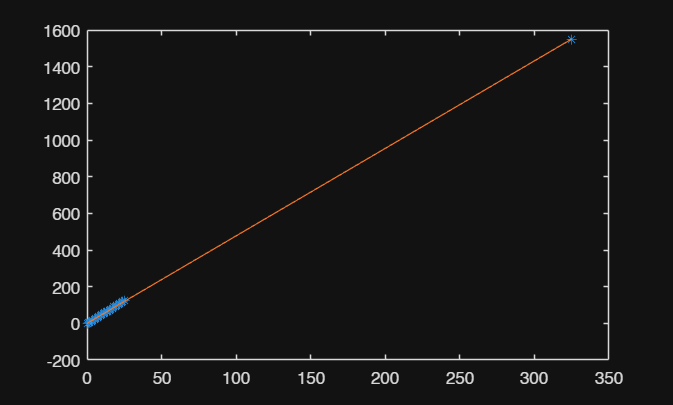

y_projected=A*inv(ATA)*ATb;
plot(x,y,'*')
hold on
plot(x,y_projected)

8. a. Generate a data for regression with a fixed m=9, c=5 for x = -25,-24, -23,…,24,25 and introducing a noise with standard deviation 3.  

clf;
m=9;
c=5;
x=-25:0.1:25

x =   -25.0000  -24.9000  -24.8000  -24.7000  -24.6000  -24.5000  -24.4000  -24.3000  -24.2000  -24.1000  -24.0000  -23.9000  -23.8000  -23.7000  -23.6000  -23.5000  -23.4000  -23.3000  -23.2000  -23.1000  -23.0000  -22.9000  -22.8000  -22.7000  -22.6000  -22.5000  -22.4000  -22.3000  -22.2000  -22.1000  -22.0000  -21.9000  -21.8000  -21.7000  -21.6000  -21.5000  -21.4000  -21.3000  -21.2000  -21.1000  -21.0000  -20.9000  -20.8000  -20.7000  -20.6000  -20.5000  -20.4000  -20.3000  -20.2000  -20.1000


n=length(x)

n = 501

y=m*x+c;
std=3;
noise=std*randn(1,n)

noise =    -0.1394   -2.9003   -1.4137    5.2057   -2.3326   -5.0514    0.5311   -0.3734   -1.2467    2.6384    1.6984    1.1278   -0.8309    1.0503   -0.8739    0.5582    1.7298    1.0190   -2.0185   -1.6110   -3.1205    2.9919   -0.0782   -1.9710    2.0332   -1.5325    1.3380    4.5499    2.8133   -0.4805   -0.3415    5.8114   -0.5124    0.9035    0.9780    2.7745    0.6459    1.0987    0.9665    8.0670    2.6282   -2.6295   -3.6523   -4.8445    5.5202   -2.4568    2.9764    1.6015   -4.5802    6.0686


ynoise=y+noise;

b. Using the data generated above, re-estimate the values of m and c. Also find the regression  line and plot it in MATLAB.

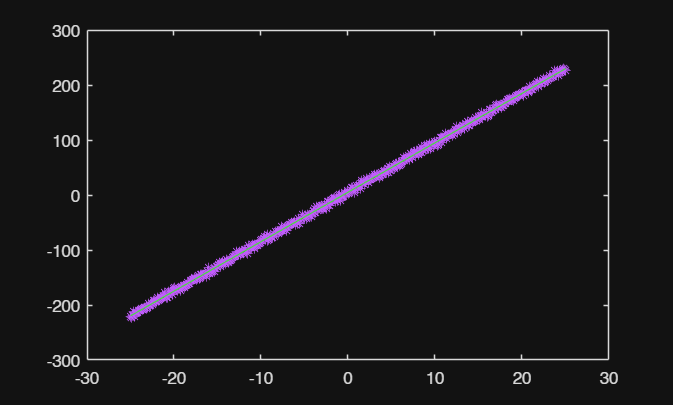

plot(x,ynoise,'*')
hold on
A=[x' ones(n,1)];
ynoise=ynoise';
m_and_c=pinv(A)*ynoise;
y_projected=A*pinv(A)*ynoise;
plot(x,y_projected);

m_and_c

m_and_c =     8.9903
    5.0157
